% 1.1.1 — Bloc 1 : Réponse échelon, Tr5%, Tr1%
clear; close all; clc;
s = tf('s');

K = 1; tau = 1;
F = K/(tau*s + 1);

figure; step(F); grid on;
title('1er ordre — K=1, \tau=1');


info = stepinfo(F);

fprintf("\n--- 1er ordre : K=1, tau=1 ---\n");


--- 1er ordre : K=1, tau=1 ---


fprintf("Temps de réponse 2%% (MATLAB) : %.4f s\n", info.SettlingTime);

Temps de réponse 2% (MATLAB) : 3.9121 s


fprintf("Théorique Tr5%% = 3*tau = %.4f s\n", 3*tau);

Théorique Tr5% = 3*tau = 3.0000 s


fprintf("Théorique Tr1%% = 5*tau = %.4f s\n\n", 5*tau);

Théorique Tr1% = 5*tau = 5.0000 s



%% 1.1.1 — Bloc 2 : Influence de tau
clear; close all; clc;
s = tf('s');

K = 1;
taus = [1 2 5];

figure; hold on; grid on;
for tau = taus
    F = K/(tau*s + 1);
    step(F);
end
legend('\tau=1','\tau=2','\tau=5');
title('Influence de \tau sur la réponse du 1er ordre');

%% 1.1.1 — Bloc 3 : Influence de K
clear; close all; clc;
s = tf('s');

tau = [1];
Ks = [1 2 5];

figure; hold on; grid on;
for K = Ks
    F = K/(tau*s + 1);
    step(F);
end
legend('K=1','K=2','K=5');
title('Influence de K sur la réponse du 1er ordre');

%% 1.1.1 — Bloc 4 : Ajout d'un zéro
clear; close all; clc;
s = tf('s');

K = 1; tau = 1;
Ts = [0 0.1 0.2 0.5 2];

figure; hold on; grid on;
for T = Ts
    F = K*(T*s + 1)/(tau*s + 1);
    step(F);
end
legend('T=0','T=0.1','T=0.2','T=0.5','T=2');
title('Influence d''un zéro sur un système du 1er ordre');

%% 1.1.1 — Bloc 5 : Retard pur (exact vs Pade)
clear; close all; clc;
s = tf('s');

K = 1; tau = 1;
taus1 = [0 0.1 1];

figure; hold on; grid on;
for tau1 = taus1
    F = K*exp(-tau1*s)/(tau*s + 1);
    step(F);
end
legend('\tau_1=0','\tau_1=0.1','\tau_1=1');
title('Retard pur exact — Réponses échelon');

%% Approximation de Padé
clear; close all; clc;
s = tf('s');

K = 1; tau = 1;
tau1 = 1;  % exemple
n = 3;     % ordre de Padé

[num,den] = pade(tau1,n);
F_pade = tf(num,den) * K/(tau*s + 1);

figure; step(F_pade); grid on;
title('Retard pur — Approximation de Padé (ordre 3)');

%% 1.1.2 — 2eme ordre : Identification + caractéristiques
clear; close all; clc;
s = tf('s');

F = 20/(s^2 + 2*s + 4);

figure; step(F); grid on;
title('2e ordre — F(s)=20/(s^2+2s+4)');


info = stepinfo(F);

fprintf("\n--- Caractéristiques temporelles ---\n");


--- Caractéristiques temporelles ---


fprintf("Temps de réponse 2%% : %.4f s\n", info.SettlingTime);

Temps de réponse 2% : 4.0379 s


fprintf("Dépassement : %.2f %%\n", info.Overshoot);

Dépassement : 16.29 %


fprintf("Temps de pic : %.4f s\n", info.PeakTime);

Temps de pic : 1.7960 s


fprintf("Temps de montée (10-90%%) : %.4f s\n", info.RiseTime);

Temps de montée (10-90%) : 0.8195 s


%% 1.1.2 — Bloc 7 : Influence de xi (avec légende corrigée)
clear; close all; clc;
s = tf('s');

K = 1; w = 1;
xis = 0:0.1:2;

figure; hold on; grid on;

legend_entries = cell(length(xis),1);   % <-- cell array fixes the error

for k = 1:length(xis)
    xi = xis(k);
    F = K*w^2/(s^2 + 2*xi*w*s + w^2);
    step(F,20);
    legend_entries{k} = sprintf('\\xi = %.1f', xi);
end

legend(legend_entries, 'Location', 'eastoutside');
title('Influence du facteur d''amortissement \xi');
xlabel('Temps (s)');

ylabel('Amplitude');

%% 1.1.2 — Bloc 8 : xi négatif
clear; close all; clc;
s = tf('s');

K = 1; w = 1;
xis = [-0.5 -1 -2];

figure; hold on; grid on;
for xi = xis
    F = K*w^2/(s^2 + 2*xi*w*s + w^2);
    step(F,10);
    fprintf("xi = %.2f -> pôles = %s\n", xi, mat2str(pole(F)));
end

xi = -0.50 -> pôles = [0.5+0.866025403784438i;0.5-0.866025403784438i]
xi = -1.00 -> pôles = [1;1]
xi = -2.00 -> pôles = [3.73205080756888;0.267949192431123]


title('Réponse échelon — \xi négatif');

%% 1.1.2 — Bloc 9 : Influence de w
clear; close all; clc;
s = tf('s');

K = 1; xi = 0.5;
ws = [1 2 5];

figure; hold on; grid on;
for w = ws
    F = K*w^2/(s^2 + 2*xi*w*s + w^2);
    step(F);
end
legend('w=1','w=2','w=5');
title('Influence de la pulsation naturelle w');

%% 1.1.2 — Bloc 10 : Ajout d'un zéro
clear; close all; clc;
s = tf('s');

K = 1; xi = 0.5; w = 1;
Ts = [0 0.5 1 5];

figure; hold on; grid on;
for T = Ts
    F = K*w^2*(T*s + 1)/(s^2 + 2*xi*w*s + w^2);
    step(F);
end
legend('T=0','T=0.5','T=1','T=5');
title('Influence d''un zéro sur un système du 2e ordre');

%% 1.1.2 — Bloc 11 : Zéro dans le demi-plan droit
clear; close all; clc;
s = tf('s');

K = 1; xi = 0.5; w = 1;
Ts = [0 -0.1 -1 -5];

figure; hold on; grid on;
for T = Ts
    F = K*w^2*(T*s + 1)/(s^2 + 2*xi*w*s + w^2);
    step(F);
end
legend('T=0','T=-0.1','T=-1','T=-5');
title('Influence d''un zéro RHP (instabilité potentielle)');

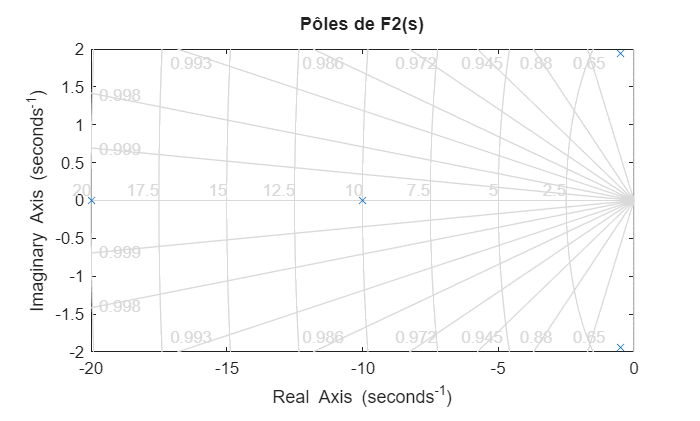

%% 1.1.3 — Bloc 13 : Approximation F2(s)
clear; close all; clc;
s = tf('s');

% Full system
F2 = 8/((0.05*s+1)*(0.1*s+1)*(s^2 + s + 4));

figure; pzmap(F2); grid on;
title('Pôles de F2(s)');

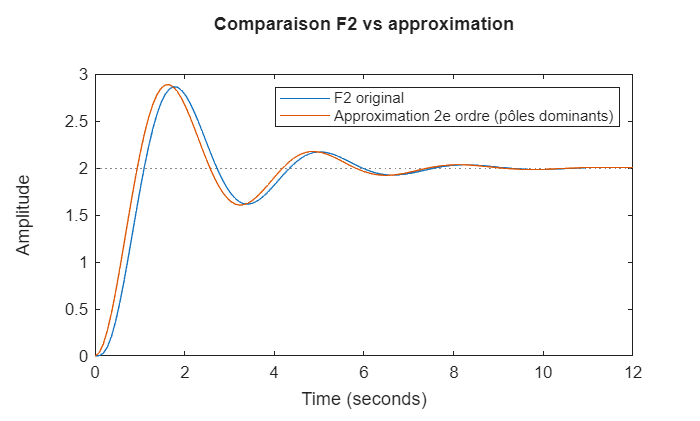


% Dominant poles = complex pair from (s^2 + s + 4)
F2_app = 8/(s^2 + s + 4);

figure; hold on; grid on;
step(F2);
step(F2_app);
legend('F2 original','Approximation 2e ordre (pôles dominants)');
title('Comparaison F2 vs approximation');